# 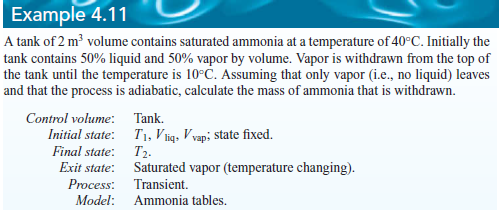

# transient process

% unknowns
u = symunit;
syms me m2 u2 x2 v2 positive;
% tank state 1 (liquid-vapor ammonia mix)
V = 2*u.m^3;
T1 = 40*u.Celsius;
Vf1 = 0.5*V;
vf1 = 0.001725*u.m^3/u.kg;
mf1 = Vf1/vf1;
Vg1 = 0.5*V;
vg1 = 0.08313*u.m^3/u.kg;
mg1 = Vg1/vg1;
m1 = mf1+mg1;
uf1 = 368.74*u.kJ/u.kg;
ug1 = 1341.0*u.kJ/u.kg;
x1 = mg1/m1;
u1 = (1-x1)*uf1+x1*ug1;
% tank state 2 (liquid-vapor ammonia mix)
eqn = sym.zeros(5,1);
T2 = 10*u.Celsius;
vf2 = 0.001600*u.m^3/u.kg;
vfg2 = 0.20381*u.m^3/u.kg;
uf2 = 225.99*u.kJ/u.kg;
ufg2 = 1099.7*u.kJ/u.kg;
eqn(1) = v2 == V/m2;
eqn(2) = v2 == vf2+x2*vfg2;
eqn(3) = u2 == uf2+x2*ufg2;
% inflow state
mi = 0;
hi = 0;
% exit state (saturated vapor ammonia)
he = (1452.0+1470.2)/2*u.kJ/u.kg;
% conservation of mass
eqn(4) = mi-me == m2-m1;
% energy equation
eqn(5) = m2*u2-m1*u1 == mi*hi-me*he;
[me m2 u2 x2 v2] = solve(eqn, [me m2 u2 x2 v2]); %#ok
me_vpa = vpa(me, 4) %#ok

$$me\_vpa = 72.75\,\mathrm{kg}$$

clear me_vpa;
clearassum;